% Problem 1_b_step_graded_junction %
% ================================ %

N_d = 10^15; % Donor doping concentration per cm^3
L_n = 2; % Length of n region in micrometer
L_p = 2; % Length of p region in micrometer
V_bi = 0.6; % Built in potential in volts
epsilon_Si = 11.8; % Dielectric constant of Silicon
epsilon_0 = 8.85 * 10^(-14); % Permittivity of free space in F/cm
n_i = 10^10; % Intrinsic carrier concentration per cm^3
T = 300 + 1.5*5; % Temperature in K (last digit : 5)
q = 1.6*10^(-19); % Charge of an electron
V_t = 0.026*(T/300); % Thermal voltage in volts

% Calculation of acceptor doping concentration and depletion widths
N_a = (n_i^2/N_d)*exp(V_bi/V_t); % Acceptor doping concentration per cm^3
W_d = sqrt(2*epsilon_Si*epsilon_0*V_bi*q^(-1)*(N_a^(-1)+N_d^(-1))); % Depletion width in cm
W_n = 10^4*(N_a/(N_a+N_d))*W_d; % Depletion width in n-side in micrometer
W_p = 10^4*(N_d/(N_a+N_d))*W_d; % Depletion width in p-side in micrometer

% Charge Profile

h = 0.001; % Step size
X = -L_p:h:L_n; % X-axis

% Volume Charge Density matrix in C/cm^3
rho_v = zeros(1,length(X));
rho_v(1,round((-W_p+L_p)/h+1):round((L_p/h)+1)) = (-q)*N_a;
rho_v(1,round((L_p/h)+2):round((W_n+L_p)/h+1)) = q*N_d;
rho_v = rho_v';

% Finite Difference matrix

A = zeros(length(X),length(X));
A(1,1) = 1;
A(length(X),length(X)) = 1;
A(length(X),length(X)-1) = -1;
for i = 2:length(X)-1
    A(i,i-1) = 1;
    A(i,i) = -2;
    A(i,i+1) = 1;
end

% L-U Decomposition

L = eye(length(X));
U = A;
for i = 2:length(X)
    for j = i:length(X)
        L(j,i-1) = U(j,i-1)/U(i-1,i-1);
        U(j,:) = U(j,:) - (U(j,i-1)/U(i-1,i-1))*U(i-1,:);
    end
end

% Implementing Forward Substitution

y = zeros(length(X),1);
for i = 1:length(X)
    a = 0;
    for j = 1:length(X)
        if(i~=j)
            a = a + L(i,j)*y(j,1);
        end
    end
    y(i,1) = rho_v(i,1) - a;
end

% Implementing Backward Substitution

x = zeros(length(X),1);
for i = length(X):-1:1
    a = 0;
    for j = 1:length(X)
        if(i~=j)
            a = a + U(i,j)*x(j,1);
        end
    end
    x(i,1) = (y(i,1) - a)/U(i,i);
end

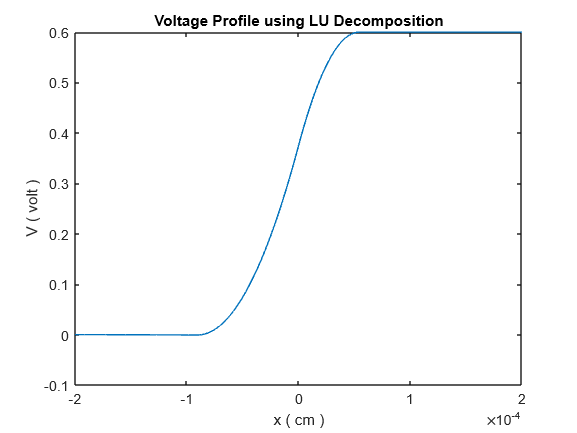

% Voltage profile

V = -(h^2*(epsilon_Si*epsilon_0)^(-1))*10^(-8)*x';

figure;
plot(X * 10^(-4),V);
xlabel('x ( cm )');
ylabel('V ( volt )');
title('Voltage Profile using LU Decomposition');

fprintf("Built-in Potential (by LU Decomposition) = %f V",max(V));

Built-in Potential (by LU Decomposition) = 0.599660 V

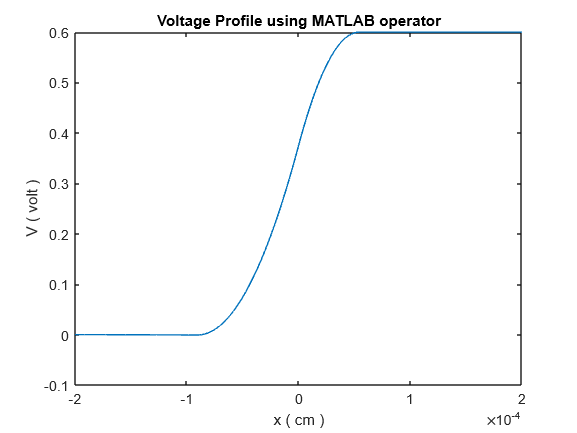

% Comparison with MATLAB A\b operator

V_test = A\(-(h^2*(epsilon_Si*epsilon_0)^(-1))*10^(-8)*rho_v);

figure;
plot(X * 10^(-4),V_test');
xlabel('x ( cm )');
ylabel('V ( volt )');
title('Voltage Profile using MATLAB operator');

fprintf("Built-in Potential (by MATLAB operator) = %f V",max(V_test));

Built-in Potential (by MATLAB operator) = 0.599660 V